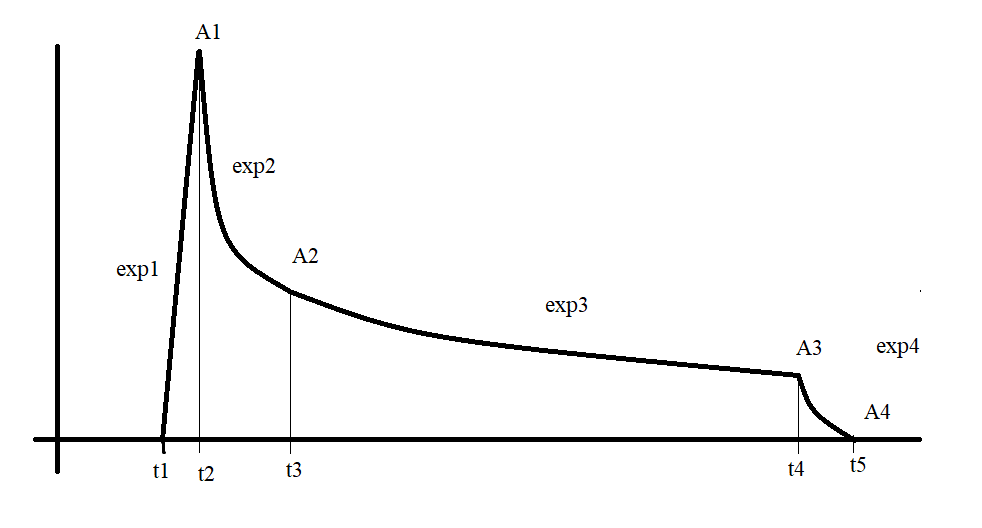

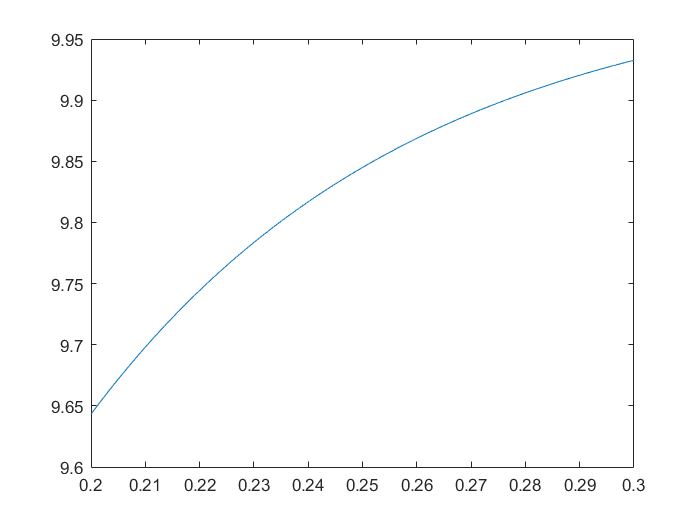

clear all
close all
Fs = 44100;
T_total = 5000;    % 5 seconds
N = floor((T_total/1000)*Fs);

t1 = 200;          % 0.5 sec - start
t2 = 300;
t3 = 1200;
t4 = 4300;
t5 = 4500;

n1 = Fs*t1/1000;
n2 = Fs*t2/1000;
n3 = Fs*t3/1000;
n4 = Fs*t4/1000;
n5 = Fs*t5/1000;
n6 = Fs*T_total / 1000;

A1 = 10;
A2 = 2;
A3 = 1;
A4 = 0;

t = [1:N] / Fs;

s0 = zeros([1 (n1-1)]);

s1 = A1 * (1 - exp(-5*t(n1:n2)/(t(n2))));
plot(t(n1:n2), s1)

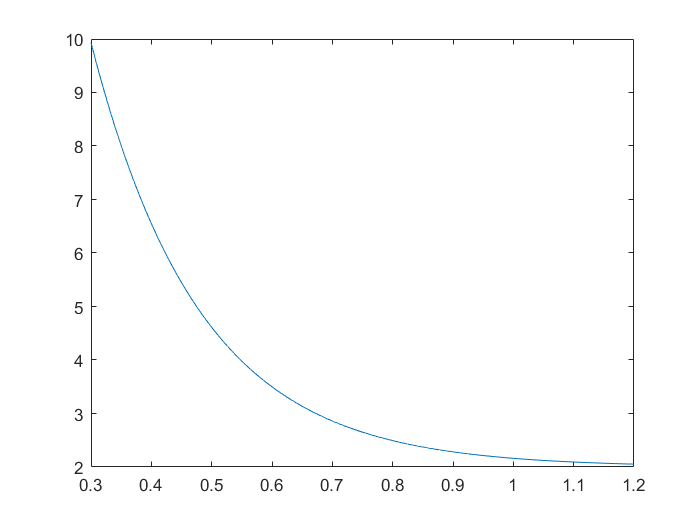


s2 = A2 + (s1(end) - A2)*exp(-5*(t(n2+1:n3) - t(n2+1))/(t(n3)-t(n2)));
plot(t(n2+1:n3), s2)

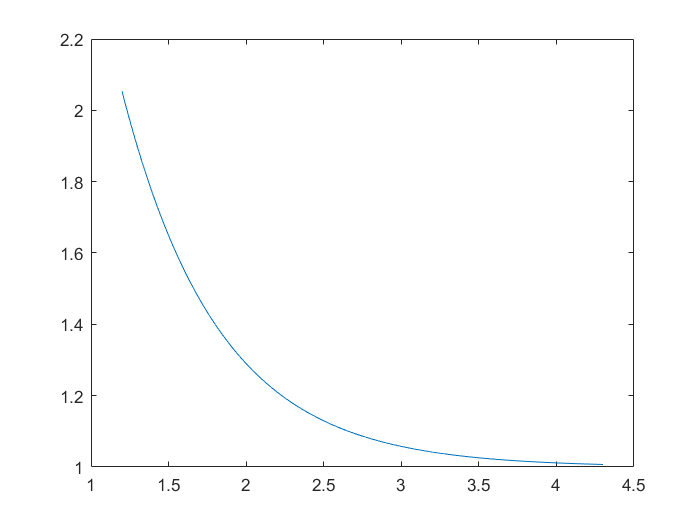


s3 = A3 + (s2(end) - A3)*exp(-5*(t(n3+1:n4) - t(n3+1))/(t(n4)-t(n3))); % To add a reverberation %+  (A3/2) * sin(2*pi*10*(t(n3+1:n4) - t(n3+1))) .* (1 - exp(-3*(t(n3+1:n4) - t(n3+1))/(t(n4)-t(n3)))) .* exp(-3*(t(n3+1:n4) - t(n3+1))/(t(n4)-t(n3)));
plot(t(n3+1:n4), s3)

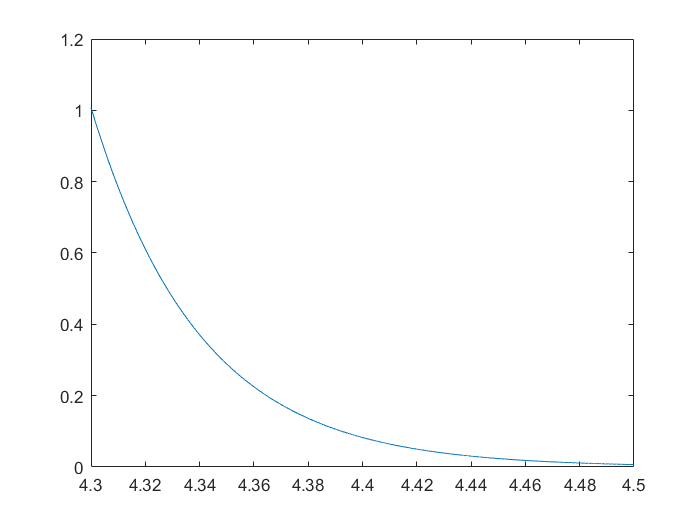


s4 = A4 + (s3(end) - A4)*exp(-5*(t(n4+1:n5) - t(n4+1))/(t(n5)-t(n4))) ;
plot(t(n4+1:n5), s4)


s5 = zeros([1 (n6-n5)])

s5 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


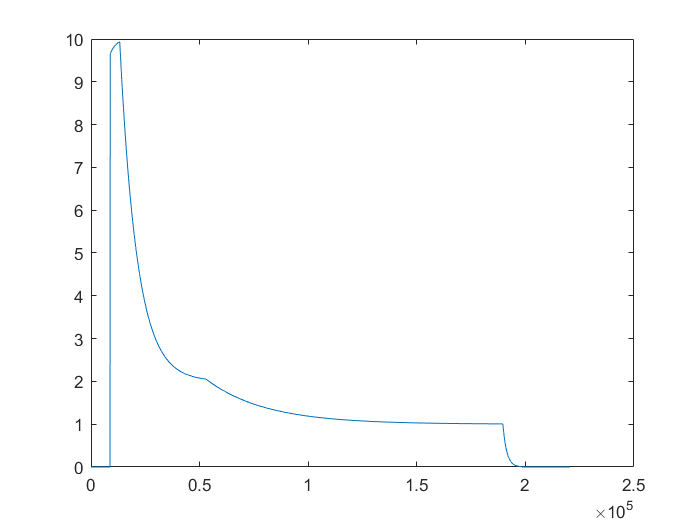


s = [s0 s1 s2 s3 s4 s5];
plot(s)

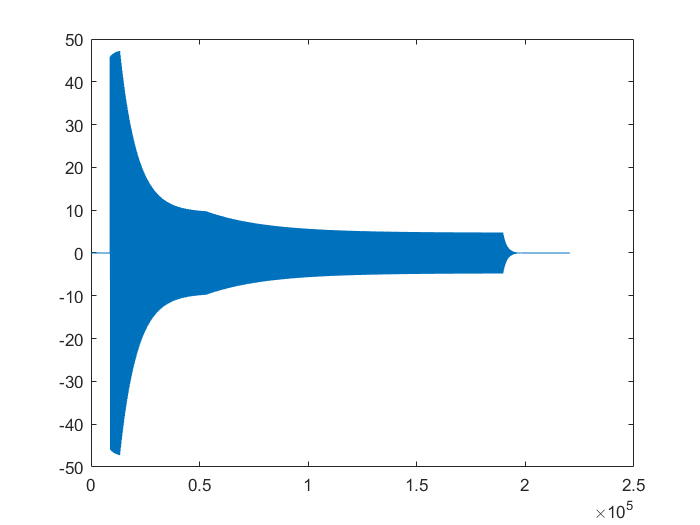


f0 = 220;
sig  = s .* sin(1*2*pi*f0*t) * 2;

sig2 = s .* sin(2*2*pi*f0*t) * 1.5;

sig3 = s .* sin(3*2*pi*f0*t) * 1.25;

sig4 = s .* sin(4*2*pi*f0*t);

sig5 = s .* sin(5*2*pi*f0*t) * 0.5;

sig6 = s .* sin(6*2*pi*f0*t) * 0.3;

sig7 = s .* sin(7*2*pi*f0*t) * 0.1;

S = sig + sig2 + sig3 + sig4 + sig5 + sig6 + sig7;

plot(S)

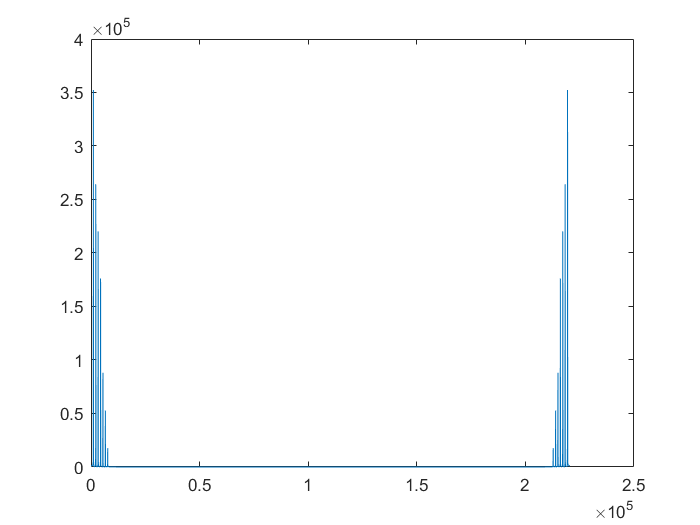


plot(abs(fft(S)))


soundsc(S, Fs)